# RUL

## Generation Prognostic data from model

Generate response data from the model. In further steps this dataset can be imported as data ensemble format.

addpath("../models/")
run("params.m");

fault_code = "1100001"

Healthy system behavior 


disp('[INFO] Parameters were loaded');

[INFO] Parameters were loaded


%%
output_path = '../data/data_gen_mdl_air_leak';
model = 'model_equation_simply_valves';

generate_data = 0;
id_max = 10;
if generate_data
    air_leak = 1;

    for i = 0:1:id_max
        output_path = '../data/data_gen_mdl_air_leak/id_' + string(i) +'/';
        
        load_system(model);
        open_system(model);
        runParallel = 0;
        processParallel = 0;
        
        % Run using Parallel Computing Toolbox
        if runParallel && isempty(gcp('nocreate'))
            parpool([2,6]);
        end
        
        % Parameters changing in the time. For system behavior simulation purposes.
        no_impact = rand()*linspace(1e-10, 1e-9, 10);
        low_impact = rand()*linspace(1e-9, 1e-8, 10);
        impact = rand()*linspace(1e-8, 1e-7, 20);
        big_impact = rand()*linspace(1e-7, 1e-6, 30);
        
        C_leak_values = [no_impact low_impact impact big_impact];
        
        
        for j = 1:numel(C_leak_values)
            tmp = Simulink.SimulationInput(model);
            tmp = setVariable(tmp, 'C_leak', C_leak_values(j));
            tmp = setVariable(tmp, 'cycle', j);
            tmp = setVariable(tmp, 'id', i);
            simin(j) = tmp;
        end
        
        if ~exist(fullfile(pwd, output_path), 'dir')
            mkdir(fullfile(pwd, output_path))
        end
        
        [status,e] = generateSimulationEnsemble(simin, ...
            fullfile(pwd, output_path), 'UseParallel', runParallel);
        if status
            disp("[INFO] Data was successfully generated")
        else
            warning("Fault in data generation")
        end
    end
end




clear all;
addpath("../utils/")
output_path = '../data/data_gen_mdl_air_leak';
ensemble = simulationEnsembleDatastore(output_path);
ensemble.SelectedVariables = ["ID"; "Cycle"];
% ensemble = handler_fix_datastore(ensemble);


ensemble.SelectedVariables = ["Time"; ... 
                              "Id"; ...
                              "LeverPosition"; ...
                              "LeverVelocity"; ...
                              "FlowContraction"; ...
                              "FlowExtrusion"; ...
                              ];


Import calculated featuretable; best feature from Monotonicity: LeverPositon_stats/Skewness

rul_featuretable = load("rul_featuretable.mat").rul_featuretable;
rul_featuretable = sortrows(rul_featuretable, "Time")

rul_featuretable = 770×54 table
    Time    Id    LeverPosition_stats/ClearanceFactor    LeverPosition_stats/CrestFactor    LeverPosition_stats/ImpulseFactor    LeverPosition_stats/Kurtosis    LeverPosition_stats/Mean    LeverPosition_stats/PeakValue    LeverPosition_stats/RMS    LeverPosition_stats/SINAD    LeverPosition_stats/SNR    LeverPosition_stats/ShapeFactor    LeverPosition_stats/Skewness    LeverPosition_stats/Std    LeverPosition_stats/THD    LeverVelocity_stats/ClearanceFactor    LeverVelocity_stats/CrestFactor    LeverVelocity_stats/ImpulseFactor    LeverVelocity_stats/Kurtosis    LeverVelocity_stats/Mean    LeverVelocity_stats/Pea

Extract some Id

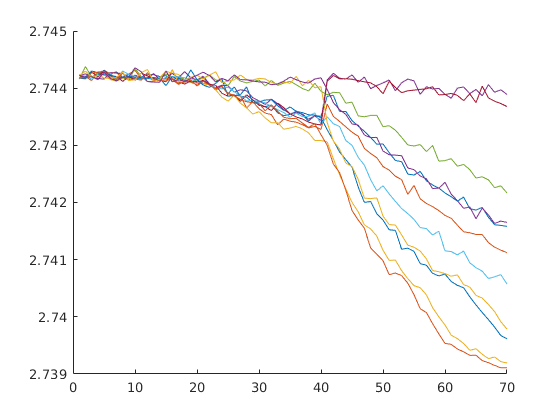

figure
for i = 0:1:10
    var = rul_featuretable(rul_featuretable.Id == i, :);
    hold on
    plot(var.Time, var.("FlowExtrusion_stats/Mean"))
end
hold off

[train_data, test_data] = split_dataset(rul_featuretable);

## Survival Covariative Model



train_data = rul_featuretable(:,["Time", "Id", "LeverPosition_stats/Skewness", "FlowExtrusion_stats/Mean"])

train_data = 770×4 table
    Time    Id    LeverPosition_stats/Skewness    FlowExtrusion_stats/Mean
    ____    __    ____________________________    ________________________

     1       0              0.16557                        2.7442         
     1      10              0.16556                        2.7442         
     1       1              0.16555                        2.7442         
     1       2              0.16556                        2.7442         
     1       3              0.16555                        2.7442         
     1       4              0.16556                        2.7442         
     1       5              0.16556                        2.7442         
     1       6              0.16556                        2.7442         
     1       7              0.16557                        2.7442         
     1       

train_data = table(train_data.Time, train_data.Id, train_data.("LeverPosition_stats/Skewness"), train_data.("FlowExtrusion_stats/Mean"), 'VariableNames', {'Time', 'Id', 'Position', 'Flow'})

train_data = 770×4 table
    Time    Id    Position     Flow 
    ____    __    ________    ______

     1       0    0.16557     2.7442
     1      10    0.16556     2.7442
     1       1    0.16555     2.7442
     1       2    0.16556     2.7442
     1       3    0.16555     2.7442
     1       4    0.16556     2.7442
     1       5    0.16556     2.7442
     1       6    0.16556     2.7442
     1       7    0.16557     2.7442
     1       8    0.16556     2.7442
     1       9    0.16556     2.7442
     2       0    0.16556     2.7442
     2      10    0.16554     2.7442
     2       1    0.16553     2.7442
     2       2    0.16555     2.7442
     2       3    0.16554     2.7442


mdl = covariateSurvivalModel('LifeTimeVariable',"Time",'LifeTimeUnit',"cycles",...
   'DataVariables',["Position","Flow", "Id"],'EncodedVariables',"Id");

fit(mdl,train_data)

Iterations terminated because relative function value changing by less than OPTIONS.TolFun


test_data = table(62, 0, 0.11, 2.74, 'VariableNames', {'Time','Id', 'Position', 'Flow'})

test_data = 1×4 table
    Time    Id    Position    Flow
    ____    __    ________    ____

     62     0       0.11      2.74


est_rul = predictRUL(mdl, test_data)

est_rul = 5.6976

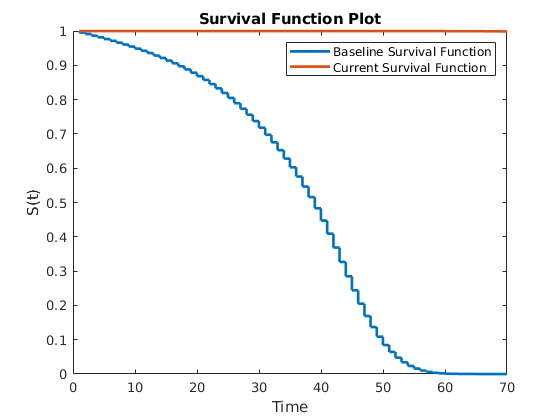

plot(mdl, test_data)

## Functions

function [dataTrain, dataTest] = split_dataset(data)
    cv = cvpartition(size(data,1), 'HoldOut', 0.3);
    idx = cv.test;      
    dataTrain = data(~idx, :);
    dataTest = data(idx, :);
end

function [accuracy] = confusion_matrix_plot_handler(mdl, features)
    required_features = mdl.RequiredVariables;
    targetLabels = features(:,"Label");
    inputTable = features(:, required_features);
    predictedLabels = mdl.predictFcn(inputTable);
    [C,order] = confusionmat(table2array(targetLabels),predictedLabels);
    accuracy = sum(table2array(targetLabels) == predictedLabels)/numel(predictedLabels);
    fprintf("Accuracy is %0.2f %% \n", accuracy*100)
    figure
    confusionchart(C, order)
end

function ensemble = handler_fix_datastore(ensemble)
% Append data
ensemble.DataVariables = [ensemble.DataVariables; "Time"; "Id"];

reset(ensemble);
while hasdata(ensemble)
    data = read(ensemble);
    cycle = data.Cycle{1,1}.Data;
    id = data.ID{1,1}.Data;
    writeToLastMemberRead(ensemble, "Time", cycle);
    writeToLastMemberRead(ensemble, "Id", id);
end
end

function ensemble = fix_label(ensemble)
reset(ensemble);
while hasdata(ensemble)
    data = read(ensemble);
    lab = data.Label{1,1};
    writeToLastMemberRead(ensemble, "Label", lab);
end
end


function signal = sim_signal_extract(signal)
    name = signal.Name;
    signal = ts2timetable(signal).(string(name))(1:end-1);
end

function [] = save_data(path, data, i)
    filename = path + "data_" + string(i) + ".mat";
    save(filename, "data")
end

function [label, r_pos_tt, r_vel_tt, r_fe_tt, r_fc_tt] = generate_residuals(reference, member, t)
    Ts = 1e-3;
    label = string(member.Label{1,1});
    position = member.LeverPosition{1,1};
    velocity = position; velocity.Data = [diff(position.Data)/Ts; 0];
    flow_ex = member.FlowExtrusion{1,1};
    flow_con = member.FlowContraction{1,1};
    
    r_pos = reference.position-position.Data;
    r_vel = reference.velocity-velocity.Data;
    r_fe = reference.flow_ex-flow_ex.Data;
    r_fc = reference.flow_con-flow_con.Data;
    
    r_pos_tt = timetable(r_pos, 'RowTimes', seconds(t), 'VariableNames', {'Data'});
    r_vel_tt = timetable(r_vel, 'RowTimes', seconds(t), 'VariableNames', {'Data'});
    r_fe_tt = timetable(r_fe, 'RowTimes', seconds(t), 'VariableNames', {'Data'});
    r_fc_tt = timetable(r_fc, 'RowTimes', seconds(t), 'VariableNames', {'Data'});
end
